# Versuch 3 - LQ-Regelung und Animation 

# Praktikum MATLAB®/Simulink® II

## Teilnehmer

#### Teilnehmer 1

Name, Vorname: Gouveia Freitas, Caio Victor

Matrikelnummer: 2328654

#### Teilnehmer 2

Name, Vorname: Brugnera Silva, Alessandro

Matrikelnummer: 2898524

## Aufgaben

Ziel dieses Versuches ist es, einen LQ-Reglerentwurf für das Doppelpendel-Modell durchzuführen und die Wirkung der Gewichtungsmatrizen $\mathbf{Q}$ und $R$ zu untersuchen. Die Simulationsergebnisse sollen in einer Animation dargestellt werden. Die folgenden Aufgaben behandeln dabei jeweils einen Einzelschritt zum Erreichen dieses Zieles.

Die verwendeten Funktionen werden teilweise in den nächsten Versuchen benötigt. Halten Sie sich daher an die vorgegebene Syntax. 

**Im Folgenden wird die Reibung vernachlässigt (**$R_{\textrm{p1}} =R_{\textrm{p2}} =0$**).**

Des Weiteren werden Sie Funktionen aus den vorherigen Versuchen benötigen (bspw. linearisierung.m). Bei der Abgmabe sind daher ALLE verwendeten Funktionen mitabzugeben. Auch solche, die bereits in vorherigen Versuchen abgegeben wurden. Diese werden in diesem Versuch **nicht** erneut bewertet, sind aber für die Ausführbarkeit, und damit die Bewertbarkeit, notwendig!

### Aufgabe 1

Vervollständigen Sie die Funktion

*[K, PoleRK] = berechneLQR(A, B, Q, R),*

die die Reglermatrix K mittels des LQR-Verfahren berechnet und diese zurückgibt. In Hinblick auf Versuch 4 soll die Funktion ebenfalls die Pole des geschlossenen Regelkreises zurückgeben.

% edit berechneLQR.m

#### Ihre Antwort:

Keine Antwort notwendig!

**Code und Plots zu Ihrer Antwort:**

% Kein Code erforderlich!

### Aufgabe 2

Gegeben sind eine Funktion *ladePendel.m*, die den Datensatz des Doppelpendels in eine Struktur zurückgibt, und eine S-Funktion *systemPendel_V3.m*, die das nichtlineare Modell beschreibt.

Implementieren Sie die Regelung in Simulink und vervollständigen Sie die in der Datei *Regelung_V3.slx* vorgegebenen Struktur. Für den Reglerentwurf soll das linearisierte Modell aus der Funktion *linearisierung.m *aus Versuch 2 verwendet werden. Für das Doppelpendel-System soll dabei das nichtlineare Modell (die gegebene S-Funktion *systemPendel_V3.m*) verwendet werden. Dieses unterscheidet sich in folgenden Punkten von der S-Funktion, die Sie in Versuch 1 erstellt haben:

- Es werden alle vier Zustände zurückgegeben.

- In den Parametern wird für die Pendeldaten die oben beschriebene Struktur benutzt.

- Es wird keine Reibung berücksichtigt.

Natürlich können Sie diese Änderungen auch in ihren eigenen Datien selbst vornehmen. In Abbildung 1.1 ist die Verwendung der S-Function gezeigt.

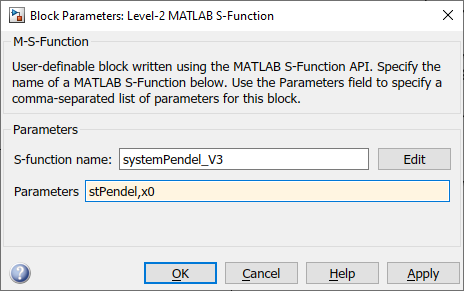

**Abbildung 1.1**: Verwendung der s-Function „systemPendel_V3“

Das Modell soll die Reglermatrix $\mathbf{K}$, die Pendeldaten, den Arbeitspunkt und den Anfangszustand ${\mathbf{x}}_0$ aus dem Workspace lesen und den Verlauf der Zustände $\mathbf{x}\left(t\right)$ mit dem Zeitvektor in den Workspace schreiben.

Hinweise:

Überlegen Sie, welche Werte das Modell des Systems für die einzelnen Arbeitspunkte zurückgibt, und welche der Regler erwartet. 

Um einen Sollgrößensprung auf das System zu geben, benutzen Sie die Anfangswerte. Geregelt wird das System immer in die Lage $\Delta \mathbf{x}=0$.

Testen Sie ihr Modell dadurch, dass Sie einen Anfangswert ungleich 0 vorgeben und interpretieren Sie den Ausgang.

**Wenn Sie Ihre Implementierung unter Zuhilfenahme eines Skriptes testen möchten, erstellen Sie bitte ein neues Skript. Eine Angabe Ihres Testcases ist für die Bewertung nicht notwendig!** 

%open_system('Regelung_V3.slx')

#### Ihre Antwort:

Keine Antwort notwendig!

**Code und Plots zu Ihrer Antwort:**

stPendel = ladePendel;
[f, h] = nonlinear_model();
x_AP = [0, 0, 0, 0];

$$conditions = \left(\begin{array}{cccc} \varphi_{1}=0 & {\mathrm{dphi}}_{1}=0 & \varphi_{2}=0 & {\mathrm{dphi}}_{2}=0 \end{array}\right)$$

A_AP =          0    1.0000         0         0
 -126.1286         0   63.0643         0
         0         0         0    1.0000
  189.1929         0 -168.1714         0


B_AP =          0
  142.8571
         0
 -214.2857


C_AP =      1     0     0     0
     0     0     1     0


D_AP =      0
     0


M_AP = 0

[A_AP, B_AP, C_AP, D_AP, M_AP] = linearisierung_v2(f,h,x_AP)
Q = diag([10 10 10 10]);
R = eye(1);

sys_steuerbar = logical
   1


Q_simetrisch = logical
   1


positive_definiert = logical
   1


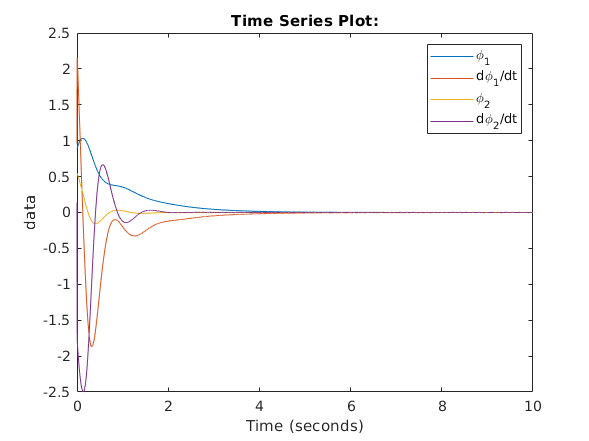

[K, poleRK] = berechneLQR(A_AP, B_AP, Q, R);
x0 = rand(1,4,'double');
AP = x_AP;
sim("Regelung_V3.slx");
figure
plot(mZustand)

legend('\phi_1', 'd\phi_1/dt', '\phi_2', 'd\phi_2/dt')

### Aufgabe 3

Schreiben Sie eine Funktion

*[vT, mX] = runPendel(stPendel, AP, K, x0 )*

die die Pendeldaten, die Reglermatrix und die Anfangswerte des Systems übergeben bekommt, und das Simulinkmodell ausführt. Diese Funktion soll den Verlauf der Zustandsgrößen mit dem dazugehörigen Zeitvektor zurückgeben.

Hinweis:

**Wenn Sie Ihre Implementierung unter Zuhilfenahme eines Skriptes testen möchten, erstellen Sie bitte ein neues Skript. Eine Angabe Ihres Testcases ist für die Bewertung nicht notwendig!** 

%edit runPendel.m

#### Ihre Antwort:

Keine Antwort notwendig!

**Code und Plots zu Ihrer Antwort:**

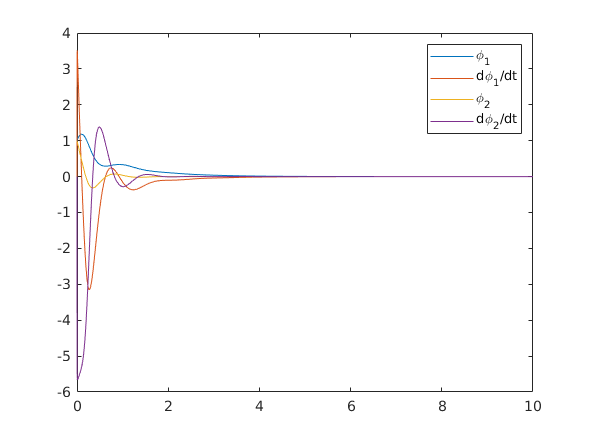

[vT, mX, vU]  = runPendel(stPendel, x_AP, K, [1 0 1 0]);
figure()
plot(vT, mX)

legend('\phi_1', 'd\phi_1/dt', '\phi_2', 'd\phi_2/dt')

### Aufgabe 4

Schreiben Sie eine Funktion

*animierePendel(vT, mX, stPendel, hAxes)*

zur Animation des Doppelpendels. Diese Funktion soll den Verlauf der Zustandsgrößen sowie den dazugehörigen Zeitvektor und die Pendeldaten übernehmen. Zudem soll diese Funktion in Hinblick auf Versuch 4 auch das Handle des Achsensystems übernehmen, in das die Animation gezeichnet werden soll. Wenn diese Variable leer ist, dann soll ein neues Figure mit Achsensystem erstellt werden.

Testen Sie Ihre Funktion mit Simulationsergebnissen im Bereich "Code und Plots zu Ihrer Antwort:" zu dieser Aufgabe. Achten Sie darauf, dass dieser Abschnitt ausführbar sein muss, ohne dass vorherige Abschnitte ausgeführt werden müssen. ("clear all" vor der Ausführung).

Hinweise:

Mit *isempty(Variablenname)* kann überprüft werden, ob eine Variable eine leere Matrix enthält. Orientieren Sie sich beim Programmieren an dem Beispiel *animierePunkt* aus dem Listing 12.3 im Skript. Geben Sie im Titel des Achsensystems die aktuelle Simulationszeit an. 

Betrachten Sie sich den Zeitvektor *vT*. Wurde ein Löser mit variabler Schrittweite verwendet, so sind die Simulationszeitpunkte nicht äquidistant, die Pause zwischen zwei Bildern der Animation müsste für jedes Bild neu bestimmt werden Es ist sinnvoll, die Daten für die Animation in einer vernünftigen konstanten Bildrate vorliegen zu haben. Hierzu kann die Funktion* xi = interp1(x,y,xi)* verwendet werden. Ein Vektor mit äquidistanten Zeitpunkten kann leicht mit *vTAnim = 0:pause:vT(end)* erzeugt werden.

In Abbildung 1.2 ist beispielhaft gezeigt, wie solch eine Animation aussehen könnte. Die gestrichelten Linien zeigen die Anfangslage des Doppelpendels und die durchgezogenen Linien stellen die aktuelle Position des Doppelpendels dar.

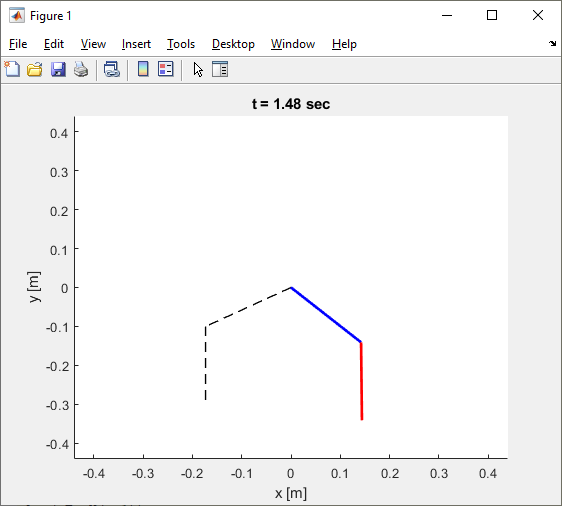

**Abbildung 1.2:** Beispiel für Animation

%edit animierePendel.m

#### Ihre Antwort:

Keine Antwort notwendig!

**Code und Plots zu Ihrer Antwort:**

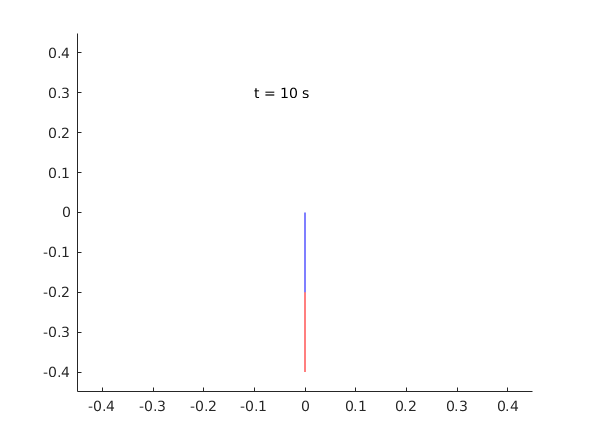

hAxes=[-.45 .45 -.45 .45];
animierePendel(vT, mX, stPendel, hAxes)

playAnimation()

### Aufgabe 5

Erweitern Sie Ihre Funktion *animierePendel.m*, sodass, wenn gewünscht, ein avi-Video generiert wird. Dazu können Sie ein weiteres Argument hinzufügen. Bedenken Sie dabei, dass die Funktion dennoch mit dem oben angegebenen Aufruf funktionieren sollte, da dies im nächsten Versuch benötigt wird.

Hinweis:

Mit dem Befehl nargin können Sie in einer Funktion die Anzahl der tatsächlich übergebenen Parameter bestimmen.

%edit animierePendel.m

#### Ihre Antwort:

Keine Antwort notwendig!

**Code und Plots zu Ihrer Antwort:**

% Kein Code erforderlich!

### Aufgabe 6

Verändern Sie die Einträge in den Matrizen $\mathbf{Q}$ und $\mathrm{R}$ und interpretieren Sie das sich daraus ändernde Systemverhalten. Achten Sie hierbei darauf, dass die Anforderungen an die Matrizen $\mathbf{Q}$ und $\mathrm{R}$ (Symmetrie, positive Definitheit) stets erfüllt sind.

- Gehen Sie von ${\mathbf{x}}_{\textrm{AP}} =\left\lbrack \begin{array}{cccc}
\frac{\pi }{3} & 0 & 0 & 0
\end{array}\right\rbrack$ und ${\mathbf{x}}_0 =\left\lbrack \begin{array}{cccc}
-\frac{\pi }{3} & 0 & 0 & 0
\end{array}\right\rbrack$ aus und vergleichen Sie die drei Fälle

                    
$$\begin{array}{l}
\mathbf{Q}=\textrm{diag}\left(\left\lbrack \begin{array}{cccc}
10 & 1 & 1 & 1
\end{array}\right\rbrack \right),\mathrm{R}=1\\
\mathbf{Q}=\textrm{diag}\left(\left\lbrack \begin{array}{cccc}
1 & 1 & 10 & 1
\end{array}\right\rbrack \right),\mathrm{R}=1\\
\mathbf{Q}=\textrm{diag}\left(\left\lbrack \begin{array}{cccc}
1 & 1 & 1 & 1
\end{array}\right\rbrack \right),\mathrm{R}=10
\end{array}$$


- Gehen Sie von ${\mathbf{x}}_{\textrm{AP}} =\left\lbrack \begin{array}{cccc}
\frac{\pi }{3} & 0 & \pi  & 0
\end{array}\right\rbrack$ und ${\mathbf{x}}_0 =\left\lbrack \begin{array}{cccc}
-\frac{\pi }{3} & 0 & \pi  & 0
\end{array}\right\rbrack$ aus und vergleichen Sie die drei Fälle

                    
$$\begin{array}{l}
\mathbf{Q}=\textrm{diag}\left(\left\lbrack \begin{array}{cccc}
10 & 1 & 1 & 1
\end{array}\right\rbrack \right),\mathrm{R}=1\\
\mathbf{Q}=\textrm{diag}\left(\left\lbrack \begin{array}{cccc}
1 & 1 & 10 & 1
\end{array}\right\rbrack \right),\mathrm{R}=1\\
\mathbf{Q}=\textrm{diag}\left(\left\lbrack \begin{array}{cccc}
1 & 1 & 1 & 1
\end{array}\right\rbrack \right),\mathrm{R}=10
\end{array}$$


Stellen Sie die Simulationsergebnisse für $M$, $\varphi_{1\;}$ und $\varphi_2$ dar und kommentieren Sie diese.

**Leiten Sie jede Betrachtung mit einer neuen Figure ein.**

#### Ihre Antwort:

Regelung um unteren AP:

AP1 = [pi/3 0 0 0];

$$conditions = \left(\begin{array}{cccc} \varphi_{1}=\frac{\pi }{3} & {\mathrm{dphi}}_{1}=0 & \varphi_{2}=0 & {\mathrm{dphi}}_{2}=0 \end{array}\right)$$

[A_AP1, B_AP1, C_AP1, D_AP1, M_AP1] = linearisierung_v2(f,h,AP1);

Qs = [[10 1 1 1]; [1 1 10 1]; [1 1 1 1]];
Rs = [1 1 10];
x0 = [-pi/3 0 0 0];
figure('Renderer', 'painters', 'Position', [10 10 1200 600])
for ii=1:3
    str = [num2str(ii), '. Q und R'];
    disp(str);
    [K, GR_pole] = berechneLQR(A_AP1, B_AP1, diag(Qs(ii,:)), Rs(ii));
    [vT, mX, vU] = runPendel(stPendel, AP1, K, x0, M_AP1);
    subplot(2,3,ii)
    plot(vT, mX)
    title(str)
    grid minor
    %legend('\phi_1', 'd\phi_1/dt', '\phi_2', 'd\phi_2/dt')

1. Q und R


sys_steuerbar = logical
   1


Q_simetrisch = logical
   1


positive_definiert = logical
   1


2. Q und R


sys_steuerbar = logical
   1


Q_simetrisch = logical
   1


positive_definiert = logical
   1


3. Q und R


sys_steuerbar = logical
   1


Q_simetrisch = logical
   1


positive_definiert = logical
   1


end
legend('\phi_1', 'd\phi_1/dt', '\phi_2', 'd\phi_2/dt')

Regelung um oberen AP:

AP2 = [pi/3 0 pi 0];

$$conditions = \left(\begin{array}{cccc} \varphi_{1}=\frac{\pi }{3} & {\mathrm{dphi}}_{1}=0 & \varphi_{2}=\pi & {\mathrm{dphi}}_{2}=0 \end{array}\right)$$

[A_AP2, B_AP2, C_AP2, D_AP2, M_AP2] = linearisierung_v2(f,h,AP2);

Qs = [[10 1 1 1]; [1 1 10 1]; [1 1 1 1]];
Rs = [1 1 10];
x0 = [-pi/3 0 pi 0];
for ii=1:3
    str = [num2str(ii), '. Q und R'];
    disp(str);
    [K, GR_pole] = berechneLQR(A_AP2, B_AP2, diag(Qs(ii,:)), Rs(ii));
    [vT, mX, vU] = runPendel(stPendel, AP2, K, x0, M_AP2);
    subplot(2,3,ii+3)
    plot(vT, mX)
    title(str)
    grid minor

1. Q und R


sys_steuerbar = logical
   1


Q_simetrisch = logical
   1


positive_definiert = logical
   1


2. Q und R


sys_steuerbar = logical
   1


Q_simetrisch = logical
   1


positive_definiert = logical
   1


3. Q und R


sys_steuerbar = logical
   1


Q_simetrisch = logical
   1


positive_definiert = logical
   1


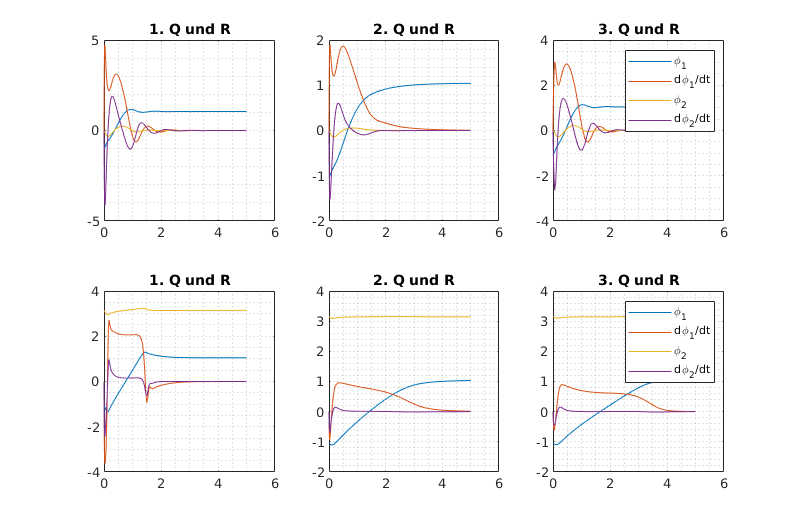

end

legend('\phi_1', 'd\phi_1/dt', '\phi_2', 'd\phi_2/dt')

Im **Arbeitspunkt 1**, mit **Q=[10 1 1 1]**, hat der erste Zustand bzw. $\phi_1$ ein größeres Gewicht in der Gütefunktion **J**, deshalb fährt er schneller nach der Endswert. Wenn **Q = [1 1 10 1]** ist, wird $\phi_2$  höher berucksichtig, aber der Anfangswert für $\phi_2$ bereits 0 ist d.h. die anderen Zustände langsamer nach den Endswert fahren. Etwas Ähnliches gilt für die 3. Möglichkeit (Einheitsmatrix Q, R=10), bei der M kleiner wird und daher die Dynamik des Systems allgemein langsamer ist.

Dasselbe geschieht in AP2, mit der Besonderheit, dass die Anfangszustände im Allgemeinen weiter vom Ende entfernt sind.

Im Arbeitspunkt 1, mit Q=[10 1 1], hat der erste Zustand oder ein größeres Gewicht in der Qualitätsfunktion J, so dass er sich schneller nach dem Endwert bewegt. Wenn Q = [1 1 1 10 1], ist er größer. Aber der Anfangswert ist bereits 0, d.h. die übrigen Zustände bewegen sich nach dem Gleichgewicht langsamer. Etwas Ähnliches gilt für die 3. Möglichkeit (Einheitsmatrix Q, R=10), bei der M kleiner wird und daher die Dynamik des Systems im Allgemeinen länger ist.

Dasselbe geschieht in AP2, mit der Besonderheit, dass die Anfangszustände im Allgemeinen weiter vom Ende entfernt sind.

### Aufgabe 7

Wenn man ungeeignete Werte für $\mathbf{Q}$, $\mathrm{R}$ oder ${\mathbf{x}}_0$ gewählt hat, wie z. B. $\mathbf{Q}=\textrm{diag}\left(\left\lbrack \begin{array}{cccc}
100 & 1 & 1 & 1
\end{array}\right\rbrack \right)$ und $\mathrm{R}=1$, bekommt man bei der Simulation numerische Probleme. Worauf ist das zurückzuführen?

#### Ihre Antwort:

Wenn die Gewichtungsmatrizen Werte zu große sind, verlassen die Zustände des linearen Modells das Einzugsgebiet. Deshalb geht nichtlineare Modell  instabil bzw. die Simulation divergiert. Das System ist zu steif von den starke Gewichtung eines Parameters, deshalb der Konvergenzbereich der angewandten numerische Verfahren zu klein ausbleibt.

**Code und Plots zu Ihrer Antwort:**

Q = [100 1 1 1];
R = 1;
[K, GR_pole] = berechneLQR(A_AP2, B_AP2, diag(Q), R);

sys_steuerbar = logical
   1


Q_simetrisch = logical
   1


positive_definiert = logical
   1


[vT, mX, vU] = runPendel(stPendel, AP2, K, x0, M_AP2);

Error using runPendel (line 6)
Derivative of state '2' in block 'Regelung_V3/Level-2 MATLAB S-Function' at time 0.058114664470908586 is not finite. The simulation will be stopped. There may be a singularity in the solution.  If not, try reducing the step size (either by reducing the fixed step size or by tightening the error tolerances)

figure
plot(vT, mX)
title(str)
grid minor
animierePendel(vT, mX, stPendel, hAxes)
playAnimation()

# Wichtige Anmerkung

Der Versuchsbericht (einer pro Gruppe) ist anhand der oben aufgeführten Fragen anzufertigen und innerhalb von einer Woche abzugeben. Die Aufgaben in der Versuchsdurchführung müssen vollständig im Bericht erscheinen. Dabei sollte ein besonderer Wert auf die Aussagekraft der Diagramme und der Screenshots gelegt werden. Die Simulationsergebnisse sollen als Diagramme mit der plot-Funktion (siehe Abschnitt Simulation, Erzeugen von Plots im Skript zu Versuch 1) dargestellt werden.  Screenshots der Scope-Blöcke von Simulink sind für die schriftliche Dokumentation aus optischen Gründen ungeeignet. Skalieren Sie die Diagramme sinnvoll, so dass das Ablesen bzw. Erkennen der interessierenden Größen möglich ist. In den Diagrammen ist eine eindeutige Achsenbezeichnung mit entsprechenden Größen und Einheiten unabdingbar. Bedenken Sie bei der Erstellung der Diagramme, dass diese auch schwarz/weiß ausgedruckt gut erkennbar und die einzelnen Graphen unterscheidbar sein müssen. Strukturieren Sie die Protokolle so, dass auch nach einer längeren Zeitpause ein rascher Einstieg in die Thematik möglich ist. Dies kann im späteren Berufsleben eine erhebliche Zeitersparnis mit sich bringen.

Eines der wichtigsten Hilfsmittel ist das Sektionsweise aufrufen. Das Live Script ist in Sektionen unterteilt. Diese können jeweils über den Punkt *Run Section* im oberen Bereich der Matlab Toolbar unter dem Punkt *Live Editor* oder per Tastenkombination **Strg + Enter **ausgeführt werden.

## Platz für Funktionen

## Platz für persönliche Hilfsfunktionen